#                                             Statistica Multivariata - Prof. Maurizio Vichi

#                                                                   Homework 1

#                                                              Alessandro Sottile

#                                                                 a.a. 2020-2021

# Esercizio 0

Rinominare il file "Homework 1.mlx" con "cognome_Multivariata.mlx". 

Gli esercizi assegnati di seguito dovranno essere svolti mediante questo strumento (Live Script) che permette contemporaneamente di scrivere parti di testo e codice nella stessa schermata e di elaborarli entrambi in un unico pdf.

Per salvare questo file come pdf: "Save" --> "Export to PDF...".

Per inserire parti di testo usare il comando "Text", per quelle di codice il comando "Code".

I passaggi effettuati per la risoluzione degli esercizi assegnati dovranno essere giustificati sia riportando il codice che commentando i risultati ottenuti e dandone, laddove possibile, una propria interpretazione.

# Esercizio 1

1.Caricare il file "Dataset Qualità della Vita". Il dataset contiene informazioni su 42 variabili rilevate sulle 107 province italiane, riportate nel vettore stringa "Province" ([https://lab24.ilsole24ore.com/qdv2018/](https://lab24.ilsole24ore.com/qdv2018/)). Le dimensioni del benessere rilevate sono 6 (non direttamente osservabili): *Ricchezza e Consumi*, *Affari e Lavoro, Ambiente e Servizi, Demografia e Società, Giustizia e Sicurezza, Cultura e Tempo Libero*. Ciascuna dimensione è definita da 7 variabili manifeste: le prime 7 fanno riferimento all dimensione *Ricchezza e Consumi*, dall'ottava alla quattordicesima alla dimensione *Affari e Lavoro*, etc. La descrizione delle variabili è disponibile sul sito [https://lab24.il](https://lab24.ilsole24ore.com/qdv2018/indexT.html.)[sole24ore.com/qdv2018/indexT.html.](https://lab24.ilsole24ore.com/qdv2018/indexT.html.)

load("Dataset Qualità della Vita")

2.Analizzare il dataset: calcolare il vettore delle medie, la matrice di varianza e covarianza e la matrice di correlazione mediante le funzioni esistenti in Matlab e scrivendo una funzione che calcoli gli stessi elementi a partire dalle definizioni studiate in classe.

Xm=mean(X)

Xm = 	1.0e+04 *

    2.1439    0.0024    0.0653    0.2293    0.0010    0.1864    0.0363    0.0010    0.0058    0.0027    0.0101    0.0028    0.0006   -0.0025    0.0001    4.5647    0.0017    0.0048    0.0421    0.0083    0.0022    0.0032    0.0007    0.0185   -0.0001    0.0011    0.0028    0.0001    0.0341    0.0188    0.2395    0.0021    0.0032    0.0061    0.0104    0.0008    0.1390    0.0069    0.0003    0.0032    0.0033    0.0401


Sx=cov(X,1) 

Sx = 	1.0e+08 *

    0.5699    0.0004    0.0158    0.0276   -0.0001    0.0449    0.0115    0.0000    0.0006   -0.0006    0.0005    0.0006    0.0001   -0.0001    0.0000    0.6162    0.0003    0.0008    0.0058    0.0000    0.0001   -0.0001    0.0000    0.0001    0.0001   -0.0000    0.0006    0.0000   -0.0072    0.0082   -0.0077   -0.0004    0.0004    0.0001   -0.0020   -0.0000    0.0088    0.0009   -0.0000    0.0011    0.0001    0.0081
    0.0004    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0158    0.0000    0.0009    0.0008   -0.0000    0.0024    0.0003    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000 

Rx=corrcoef(X)

Rx =     1.0000    0.9040    0.7029    0.7159   -0.2050    0.7164    0.6142    0.0514    0.7617   -0.6896    0.2721    0.3926    0.3974   -0.1660    0.4474    0.7598    0.2610    0.3820    0.8004    0.5878    0.4206   -0.1433    0.0718    0.0378    0.6743   -0.0465    0.5620    0.4420   -0.5575    0.5462   -0.1766   -0.4652    0.1945    0.0337   -0.2159   -0.0209    0.2193    0.4287   -0.2669    0.5290    0.0804    0.6494
    0.9040    1.0000    0.7226    0.8178   -0.3906    0.7307    0.6536    0.0079    0.8667   -0.7832    0.4129    0.4951    0.3488   -0.2084    0.5081    0.8522    0.3695    0.4551    0.8903    0.6748    0.3997   -0.3010    0.0544    0.0912    0.7777   -0.0068    0.6355    0.5148   -0.6590    0.5946   -0.2663   -0.5636    0.1747    0.0925   -0.3291    0.0182    0.2766    0.4958   -0.2552    0.5656    0.0406    0.7407
    0.7029    0.7226    1.0000    0.5041   -0.1170    0.9787    0.4552    0.0037    0.5380   -0.4675    0.4278    0.1122    0.1998   -0.0679    0.2654   

Xm rappresenta il vettore delle medie.

Sx rappresenta la matrice delle  varianze e covarianze.

Rx  Rappresenta la matrice delle correlazioni.

[Xm,Sx,Rx]=Funzione1(X)

Xm = 	1.0e+04 *

    2.1439
    0.0024
    0.0653
    0.2293
    0.0010
    0.1864
    0.0363
    0.0010
    0.0058
    0.0027


Sx = 	1.0e+08 *

    0.5699    0.0004    0.0158    0.0276   -0.0001    0.0449    0.0115    0.0000    0.0006   -0.0006    0.0005    0.0006    0.0001   -0.0001    0.0000    0.6162    0.0003    0.0008    0.0058    0.0000    0.0001   -0.0001    0.0000    0.0001    0.0001   -0.0000    0.0006    0.0000   -0.0072    0.0082   -0.0077   -0.0004    0.0004    0.0001   -0.0020   -0.0000    0.0088    0.0009   -0.0000    0.0011    0.0001    0.0081
    0.0004    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0158    0.0000    0.0009    0.0008   -0.0000    0.0024    0.0003    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000 

Rx =     1.0000    0.9040    0.7029    0.7159   -0.2050    0.7164    0.6142    0.0514    0.7617   -0.6896    0.2721    0.3926    0.3974   -0.1660    0.4474    0.7598    0.2610    0.3820    0.8004    0.5878    0.4206   -0.1433    0.0718    0.0378    0.6743   -0.0465    0.5620    0.4420   -0.5575    0.5462   -0.1766   -0.4652    0.1945    0.0337   -0.2159   -0.0209    0.2193    0.4287   -0.2669    0.5290    0.0804    0.6494
    0.9040    1.0000    0.7226    0.8178   -0.3906    0.7307    0.6536    0.0079    0.8667   -0.7832    0.4129    0.4951    0.3488   -0.2084    0.5081    0.8522    0.3695    0.4551    0.8903    0.6748    0.3997   -0.3010    0.0544    0.0912    0.7777   -0.0068    0.6355    0.5148   -0.6590    0.5946   -0.2663   -0.5636    0.1747    0.0925   -0.3291    0.0182    0.2766    0.4958   -0.2552    0.5656    0.0406    0.7407
    0.7029    0.7226    1.0000    0.5041   -0.1170    0.9787    0.4552    0.0037    0.5380   -0.4675    0.4278    0.1122    0.1998   -0.0679    0.2654   

Usando la funzione creata otteniamo gli stessi valori di prima.

3. Calcolare la matrice di correlazione a partire da quella di varianza e covarianza e rappresentarla mediante una heatmap. Commentare il risultato.

U107= ones(107,1);
Jc=eye(107)-1/107*U107*U107';
S=(1/107)*X'*Jc*X;
D=diag(diag(S));
D=D.^(0.5);
Rricav = D^(-1)*S*D^(-1) 

Rricav =     1.0000    0.9040    0.7029    0.7159   -0.2050    0.7164    0.6142    0.0514    0.7617   -0.6896    0.2721    0.3926    0.3974   -0.1660    0.4474    0.7598    0.2610    0.3820    0.8004    0.5878    0.4206   -0.1433    0.0718    0.0378    0.6743   -0.0465    0.5620    0.4420   -0.5575    0.5462   -0.1766   -0.4652    0.1945    0.0337   -0.2159   -0.0209    0.2193    0.4287   -0.2669    0.5290    0.0804    0.6494
    0.9040    1.0000    0.7226    0.8178   -0.3906    0.7307    0.6536    0.0079    0.8667   -0.7832    0.4129    0.4951    0.3488   -0.2084    0.5081    0.8522    0.3695    0.4551    0.8903    0.6748    0.3997   -0.3010    0.0544    0.0912    0.7777   -0.0068    0.6355    0.5148   -0.6590    0.5946   -0.2663   -0.5636    0.1747    0.0925   -0.3291    0.0182    0.2766    0.4958   -0.2552    0.5656    0.0406    0.7407
    0.7029    0.7226    1.0000    0.5041   -0.1170    0.9787    0.4552    0.0037    0.5380   -0.4675    0.4278    0.1122    0.1998   -0.0679    0.265

Si è giunti al risultato tramite la formula della matrice di correlazione

het1=heatmap(Rricav)

het1 =   HeatmapChart with properties:

        XData: {42×1 cell}
        YData: {42×1 cell}
    ColorData: [42×42 double]

  Show all properties


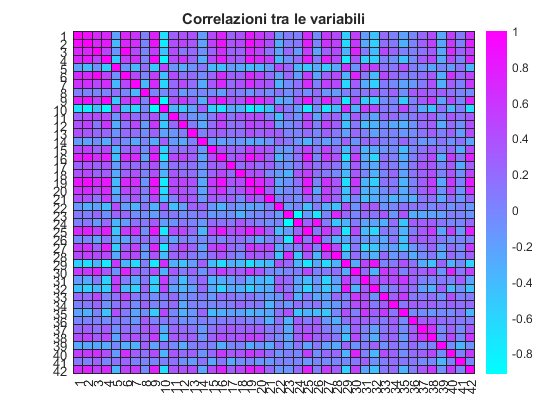

het1.Title = 'Correlazioni tra le variabili';
het1.Colormap = cool;

het2=heatmap(Rx)

het2 =   HeatmapChart with properties:

        XData: {42×1 cell}
        YData: {42×1 cell}
    ColorData: [42×42 double]

  Show all properties


het2.Title = 'Correlazioni tra le variabili';
het2.Colormap = cool;

i due heatmap coincidono.

Guardando il grafico possiamo notare che non sono presenti forti tendenze riguardo al modo in cui si distribuiscono i valori in un ottica generale, però si può notare legami tra variabili appartenenti allo stesso dominio.

Ad esempio tutte le variabili afferenti al primo dominio, ovvero le variabili comprese tra 1 e 7 estremi inclusi, hanno un deciso grado di correlazione positiva tra loro, stessa cosa si può dire per quelle afferenti al terzo dominio.

4. Scegliere una variabile per ciascuna dimensione e rappresentare i dati per coppie di variabili (suggerimento: cercare una funzione in Matlab per ottenere una rappresentazione compatta).

Oeh = X(:,[7 13 21  24 29 37]);
NomiIndici = {'spesa pro/capite in turismo'; 'Start up'; ' Escursione termica'; 
    'Indice Vecchiaia'; 'Durata Media Processi'; 'Sportività'};

Le variabili sono state scelte in modo casuale.

Il vettore NomiIndici contiene i nomi degli indici selezionati dall'analisi effettuata da Il Sole 24 Ore

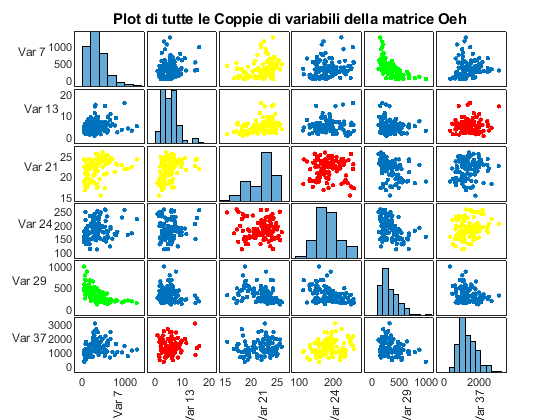

[S,AX,BigAx,H,HAx] = plotmatrix(Oeh);
ylabel(AX(1,1),'Var 7','Rotation',0,'HorizontalAlignment','right');
ylabel(AX(2,1),'Var 13','Rotation',0,'HorizontalAlignment','right');
ylabel(AX(3,1),'Var 21','Rotation',0,'HorizontalAlignment','right');
ylabel(AX(4,1),'Var 24','Rotation',0,'HorizontalAlignment','right');
ylabel(AX(5,1),'Var 29','Rotation',0,'HorizontalAlignment','right');
ylabel(AX(6,1),'Var 37','Rotation',0,'HorizontalAlignment','right');
xlabel(AX(end,1),'Var 7','Rotation',90,'HorizontalAlignment','right');
xlabel(AX(end,2),'Var 13','Rotation',90,'HorizontalAlignment','right');
xlabel(AX(end,3),'Var 21','Rotation',90,'HorizontalAlignment','right');
xlabel(AX(end,4),'Var 24','Rotation',90,'HorizontalAlignment','right');
xlabel(AX(end,5),'Var 29','Rotation',90,'HorizontalAlignment','right');
xlabel(AX(end,6),'Var 37','Rotation',90,'HorizontalAlignment','right');
title(BigAx,'Plot di tutte le Coppie di variabili della matrice Oeh')
S(2,6).Color='r';
S(6,2).Color='r';
S(4,3).Color='r';
S(3,4).Color='r';
S(1,5).Color='g';
S(5,1).Color='g';
S(3,1).Color='y';
S(1,3).Color='y';
S(3,2).Color='y';
S(2,3).Color='y';
S(6,4).Color='y';
S(4,6).Color='y';

La matrice scelta fa notare, grazie all'uso del plotmatrix, vari aspetti degni di nota:

Inanzitutto si può partire analizzando gli istogrammi che rapresentano la distribuzione della variabili, la maggior parte di queste infatti si distribuiscono in modo asimmetrico, denotando la presenza di alcuni dati distanti dal corpo centrale della distribuzione.

Si nota dagli scatterplot, che alcune coppie presenti nel grafico possono essere correlate positivamente, negativamente o addirittura incorrelate.

Ad esempio le coppie (13,37) e (21,24) formano grafici con nuvole di punti che non seguono una particolare tendenza, quindi possono essere considerate incorrelate.

Analizzando la coppia (7,29) è facile notare come vi sia una forte correlazione negativa, infatti a valori alti di una corrisponde un valore basso dell'altra.

Infine le coppie (7,21),(13,21) e (24,37) godono di una discreta correlazione positiva.

Tutti questi legami possono essere riassunti tramite la matrice di correlazione:

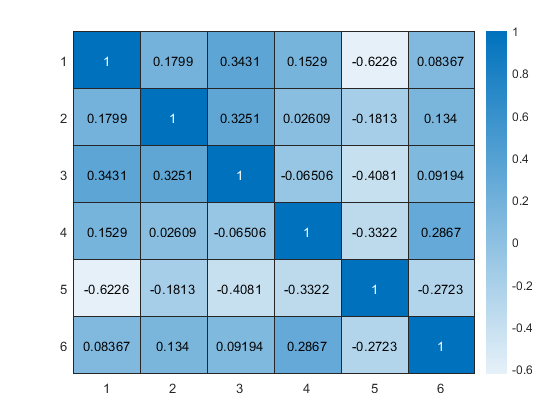

heatmap(corrcoef(Oeh))

5. Campionare casualmente 50 province dalle 107 totali.

VettIndicatrice=(1:107)';
MatrIndicatrice= [ VettIndicatrice X];

CampioneIndicatore = datasample(MatrIndicatrice,50,"Replace",false);
Campione =  CampioneIndicatore(:,2:43) 

Campione = 	1.0e+04 *

    3.3068    0.0032    0.0760    0.2213    0.0003    0.2000    0.0996    0.0007    0.0067    0.0017    0.0077    0.0043    0.0016   -0.0025    0.0001    6.3549    0.0001    0.0138    0.0523    0.0083    0.0022    0.0032    0.0006    0.0258    0.0003    0.0014    0.0024    0.0001    0.0191    0.0480    0.3688    0.0006    0.0037    0.0074    0.0049    0.0005    0.1491    0.0122    0.0002    0.0052    0.0033    0.0912
    4.2866    0.0029    0.0830    0.2816    0.0006    0.2200    0.0427    0.0010    0.0067    0.0011    0.0091    0.0051    0.0007   -0.0030    0.0001    4.9480    0.0006    0.0031    0.0512    0.0084    0.0025    0.0031    0.0008    0.0152    0.0001    0.0009    0.0047    0.0001    0.0244    0.0110    0.1695    0.0017    0.0014    0.0025    0.0022    0.0004    0.1022    0.0067    0.0002    0.0027    0.0031    0.0567
    2.4197    0.0027    0.0470    0.2537    0.0006    0.1450    0.0553    0.0009    0.0065    0.0020    0.0102    0.0038    0.0007   -0

Ho estratto dalla matrice CampioneIndicatore una sotto-matrice che non contiene più la colonna 1, ovvero quella che serve per indicare a quale provincia appartiene ogni riga di dati.

PosizioniCampione = CampioneIndicatore(:,1)

PosizioniCampione =     98
    97
    99
    59
    48
    47
    25
    93
    42
   101


6. Ricodificare la variabile "Furti di autovetture" in 6 classi con percentuali 5%, 20%, 25%, 

30%, 10%, 10%. Si veda il punto 1 per la descrizione delle variabili.

FurtiAutovetture = Campione(:,35);

Guardando il link del punto 1, si scopre che la colonna d'interesse è la 35

ClassiFurti = quantile(FurtiAutovetture,[0 0.05 0.25 0.50 0.80 0.90 1])

ClassiFurti =    11.4000   15.9000   41.5000   58.3500  184.8000  337.9500  566.4000


ClassiFurti è il vettore che rappresenta gli estremi delle classi

DivisioneFurti= discretize(FurtiAutovetture,ClassiFurti,"categorical")

DivisioneFurti = 50×1 categorical array
     [41.5, 58.35) 
     [15.9, 41.5) 
     [15.9, 41.5) 
     [337.95, 566.4] 
     [41.5, 58.35) 
     [41.5, 58.35) 
     [184.8, 337.95) 
     [15.9, 41.5) 
     [15.9, 41.5) 
     [15.9, 41.5) 
     [58.35, 184.8) 
     [184.8, 337.95) 
     [58.35, 184.8) 
     [11.4, 15.9) 
     [58.35, 184.8) 
     [337.95, 566.4] 
     [58.35, 184.8) 
     [184.8, 337.95) 
     [41.5, 58.35) 
     [41.5, 58.35) 
     [337.95, 566.4] 
     [11.4, 15.9) 
     [184.8, 337.95) 
     [15.9, 41.5) 
     [41.5, 58.35) 
     [41.5, 58.35) 
     [41.5, 58.35) 
     [15.9, 41.5) 
     [41.5, 58.35) 
     [58.35, 184.8) 


Si è ottenuta la divisione usando gli estremi precedenti

7. Ricodificare la variabile "Scippi e borseggi" in 5 classi con percentuali 15%, 20%, 30%, 20%, 15%. Si veda il punto 1 per la descrizione delle variabili.

ScippiBorseggi = Campione(:,30);
ClassiScippi = quantile(ScippiBorseggi,[0 0.15 0.35 0.65 0.85 1]) 

ClassiScippi = 	1.0e+03 *

    0.0218    0.0518    0.1075    0.2045    0.4233    1.0729


DivisioneScippi= discretize(ScippiBorseggi,ClassiScippi,"categorical") 

DivisioneScippi = 50×1 categorical array
     [423.3, 1072.9] 
     [107.5, 204.5) 
     [107.5, 204.5) 
     [204.5, 423.3) 
     [204.5, 423.3) 
     [51.8, 107.5) 
     [51.8, 107.5) 
     [107.5, 204.5) 
     [21.8, 51.8) 
     [423.3, 1072.9] 
     [107.5, 204.5) 
     [51.8, 107.5) 
     [107.5, 204.5) 
     [107.5, 204.5) 
     [21.8, 51.8) 
     [107.5, 204.5) 
     [423.3, 1072.9] 
     [204.5, 423.3) 
     [107.5, 204.5) 
     [51.8, 107.5) 
     [423.3, 1072.9] 
     [21.8, 51.8) 
     [107.5, 204.5) 
     [107.5, 204.5) 
     [51.8, 107.5) 
     [204.5, 423.3) 
     [423.3, 1072.9] 
     [107.5, 204.5) 
     [107.5, 204.5) 
     [423.3, 1072.9] 


Per ottenere la ricodifica, sono stati usati gli stessi passaggi del punto precedente

8. Individuare la distribuzione semplice in classi delle due variabili al punto 6 e 7.

u6=ones(6,1) ;
u5=ones(5,1); % vettore di elementi unitari
I6=eye(6); % matrice identità
I5=eye(5);
BF=I6(DivisioneFurti ,:); % matrice indicatrice
BS=I5(DivisioneScippi,:);
CS= BS'*BS*u5

CS =      7
     9
    16
    10
     8


CF= BF'*BF*u6 % vettore frequenze assolute

CF =      2
    10
    13
    15
     5
     5


Applicando la funzione tabulate ottengo la stessa divisione:

tabulate(DivisioneScippi) 

            Value    Count   Percent
     [21.8, 51.8)        7     14.00%
    [51.8, 107.5)        9     18.00%
   [107.5, 204.5)       16     32.00%
   [204.5, 423.3)       10     20.00%
  [423.3, 1072.9]        8     16.00%


tabulate(DivisioneFurti)

            Value    Count   Percent
     [11.4, 15.9)        2      4.00%
     [15.9, 41.5)       10     20.00%
    [41.5, 58.35)       13     26.00%
   [58.35, 184.8)       15     30.00%
  [184.8, 337.95)        5     10.00%
  [337.95, 566.4]        5     10.00%


9. Calcolare la tabella di contingenza con frequenze assolute, quella normalizzata per riga e quella normalizzata per colonna delle due variabili ricodificate in classi al punto 6 e 7.

CF= BF'*BF*u6 ;
CS= BS'*BS*u5;
Cfs = BF'*BS % matrice frequenze assolute

Cfs =      1     0     1     0     0
     1     0     5     3     1
     1     3     2     5     2
     4     4     4     0     3
     0     2     1     1     1
     0     0     3     1     1


matr = [Cfs,CF;CS',size(BF,1)] 

matr =      1     0     1     0     0     2
     1     0     5     3     1    10
     1     3     2     5     2    13
     4     4     4     0     3    15
     0     2     1     1     1     5
     0     0     3     1     1     5
     7     9    16    10     8    50


% ho ottenuto la tabella di contingenza doppia
ca=(CF'*u6)^-1*CF 

ca =     0.0400
    0.2000
    0.2600
    0.3000
    0.1000
    0.1000


% vettore frequenze relative
cb=(CS'*u5)^-1*CS

cb =     0.1400
    0.1800
    0.3200
    0.2000
    0.1600


r=pinv(BF)*BS % normalizzo per riga

r =     0.5000         0    0.5000         0         0
    0.1000         0    0.5000    0.3000    0.1000
    0.0769    0.2308    0.1538    0.3846    0.1538
    0.2667    0.2667    0.2667         0    0.2000
         0    0.4000    0.2000    0.2000    0.2000
   -0.0000   -0.0000    0.6000    0.2000    0.2000


c=(pinv(BS)*BF)' % normalizzo per colonna

c =     0.1429         0    0.0625         0   -0.0000
    0.1429         0    0.3125    0.3000    0.1250
    0.1429    0.3333    0.1250    0.5000    0.2500
    0.5714    0.4444    0.2500         0    0.3750
         0    0.2222    0.0625    0.1000    0.1250
         0         0    0.1875    0.1000    0.1250


TabNormR=[r , ca; cb',size(BF,1)/size(BF,1) ] % ottengo le due tabelle 

TabNormR =     0.5000         0    0.5000         0         0    0.0400
    0.1000         0    0.5000    0.3000    0.1000    0.2000
    0.0769    0.2308    0.1538    0.3846    0.1538    0.2600
    0.2667    0.2667    0.2667         0    0.2000    0.3000
         0    0.4000    0.2000    0.2000    0.2000    0.1000
   -0.0000   -0.0000    0.6000    0.2000    0.2000    0.1000
    0.1400    0.1800    0.3200    0.2000    0.1600    1.0000


TabNormC=[c , ca; cb',size(BF,1)/size(BF,1) ]

TabNormC =     0.1429         0    0.0625         0   -0.0000    0.0400
    0.1429         0    0.3125    0.3000    0.1250    0.2000
    0.1429    0.3333    0.1250    0.5000    0.2500    0.2600
    0.5714    0.4444    0.2500         0    0.3750    0.3000
         0    0.2222    0.0625    0.1000    0.1250    0.1000
         0         0    0.1875    0.1000    0.1250    0.1000
    0.1400    0.1800    0.3200    0.2000    0.1600    1.0000


10. Calcolare il $\chi^{2}
$, assoluto e relativo, tra le due distribuzioni ricodificate in classi al punto 6 e 7. Utilizzare una funzione esistente in Matlab (che include il calcolo della distribuzione doppia) e scrivere una funzione che permetta di calcolare il chi-quadro nei vari modi studiati in classe.

[tbl,chi2] = crosstab(DivisioneFurti,DivisioneScippi) % ottengo il chiquadro assoluto

tbl =      1     0     1     0     0
     1     0     5     3     1
     1     3     2     5     2
     4     4     4     0     3
     0     2     1     1     1
     0     0     3     1     1


chi2 = 21.5041

h= size(tabulate(DivisioneScippi),1) %numero righe

h = 5

k= size(tabulate(DivisioneFurti),1) %numero colonne

k = 6

n= size(DivisioneFurti,1) % numero di osservazioni

n = 50

ChiMax= min(h-1,k-1)*n %rappresenta il chiquadro massimo

ChiMax = 200

ChiRel= [,chi2]/ChiMax %rappresenta il chiquadro relativo

ChiRel = 0.1075

Usando la funzione ChiquadroFinale, nella quale bisogna specificare L'argomento Tipo, la funzione calcolerà il chiquadro usando il metodo dato in imput.

ChiquadroFinale(BF,BS,1)

Stampa2 = 21.5041

ChiquadroFinale(BF,BS,2)

Stampa1 = 21.5041

ans = 21.5041

ChiquadroFinale(BF,BS,3)

Stampa3 = 21.5041

11. Calcolare il vettore delle medie delle variabili "Delitti di stupefacenti" e "Cause pendenti ultratriennali" condizionatamente alla distribuzione in classi calcolata al punto 6. Si veda il punto 1 per la descrizione delle variabili.

DelittidiStuepfecenti = Campione(:,34);
CausePendentiUltratriennali = Campione(:,32);
MedieCondizionateDelitti =pinv(BF)*DelittidiStuepfecenti

MedieCondizionateDelitti =    62.5500
   63.5900
   54.8846
   52.8467
   62.8600
   69.4000


MedieCondizionateCause = pinv(BF)*CausePendentiUltratriennali 

MedieCondizionateCause =    11.4500
   18.7800
   16.2154
   24.2067
   17.4000
   29.3200


% ho ottenuto le medie condizionate

12. Calcolare la varianza delle variabili “Consumi” e “Prezzi medi di vendita delle case”. Si veda il punto 1 per la descrizione delle variabili.

Consumi =  Campione(:,4);
PrezziMediCase =  Campione(:,6); % estraggo i valori richiesti
I50=eye(50);
Jcc = I50-1/50*ones(50)*ones(50); % matrice di centratura
ConsumiCentrati = Jcc*Consumi; % costruisco ora le matrici dei dati centrati
PrezziCentrati = Jcc*PrezziMediCase;
VarianzaConsumi = (ConsumiCentrati'*ConsumiCentrati)/50 

VarianzaConsumi = 1.2839e+10

VarianzaPrezzi = (PrezziCentrati'*PrezziCentrati)/50

VarianzaPrezzi = 9.4512e+09

13. Calcolare la covarianza tra le variabili “PIL pro capite” e “Depositi pro capite”.

Pil= Campione(:,1);
Depositi = Campione(:,2);
I50=eye(50);
Jcc = I50-1/50*ones(50)*ones(50);
PILCentrati = Jcc*Pil;    
DepositiCentrati = Jcc*Depositi;
CovPilDepositi = 1/50 *PILCentrati'*DepositiCentrati 

CovPilDepositi = 1.2657e+09

14. Calcolare la matrice dei dati standardizzati mediante la funzione esistente in Matlab e scrivendo una funzione sulla base della definizione studiata in classe.

MatriceDatiStandardizzati=zscore(Campione,1)

MatriceDatiStandardizzati =     1.3966    1.1779    0.1894   -0.1962   -1.0016    0.0179    2.8983   -2.4729    0.8781   -0.7645   -0.9778    0.8720    3.1118   -0.0323    0.5794    1.4798   -1.1034    3.0620    0.9532    0.0888   -0.0968    0.0271   -1.2429    2.3987    1.2146    2.0062   -0.2931    0.0659   -0.8723    1.1415    2.1383   -1.2168    0.0181    0.8102   -0.5406   -0.9298    0.3420    1.9172   -0.8871    0.4740    0.1516    2.7309
    2.6549    0.7522    0.4071    0.9940   -0.6155    0.2411    0.2993   -0.0362    0.9065   -1.2549   -0.4591    1.3413    0.2383   -0.9287    1.4314    0.2389   -0.7643   -0.6709    0.8403    1.5285    1.1020   -0.1693    0.4802   -0.8155    0.4945   -1.2894    1.4592    0.8897   -0.5625   -0.4920   -1.2509   -0.3280   -0.7555   -1.7923   -0.7377   -1.2751   -0.5257   -0.0218   -0.8871   -0.3023    0.0100    0.8158
    0.2573    0.5546   -0.7122    0.4433   -0.5583   -0.5959    0.8748   -0.4292    0.6415   -0.5233   -0.0179    0.6320    0.3593

Standard(Campione)

n = 50

In =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0  

jcc =     0.9800   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200
   -0.0200    0.9800   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   -0.0200   

Sx = 	1.0e+08 *

    0.6063    0.0005    0.0170    0.0287   -0.0001    0.0479    0.0127   -0.0000    0.0007   -0.0007    0.0006    0.0008    0.0001   -0.0001    0.0000    0.6605    0.0003    0.0007    0.0062    0.0000    0.0001   -0.0001    0.0000   -0.0000    0.0001   -0.0000    0.0006    0.0000   -0.0083    0.0082   -0.0100   -0.0005    0.0000    0.0001   -0.0034   -0.0000    0.0049    0.0009   -0.0000    0.0012    0.0001    0.0098
    0.0005    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0170    0.0000    0.0010    0.0008   -0.0000    0.0028    0.0004   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000 

D = 	1.0e+08 *

    0.6063         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0010         0         0         0         0         0         0         0         0         0         0         0  

Dnew = 	1.0e+04 *

    0.7787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0007         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0322         0         0         0         0         0         0         0         0         0         0         

Stampa =     1.3966    1.1779    0.1894   -0.1962   -1.0016    0.0179    2.8983   -2.4729    0.8781   -0.7645   -0.9778    0.8720    3.1118   -0.0323    0.5794    1.4798   -1.1034    3.0620    0.9532    0.0888   -0.0968    0.0271   -1.2429    2.3987    1.2146    2.0062   -0.2931    0.0659   -0.8723    1.1415    2.1383   -1.2168    0.0181    0.8102   -0.5406   -0.9298    0.3420    1.9172   -0.8871    0.4740    0.1516    2.7309
    2.6549    0.7522    0.4071    0.9940   -0.6155    0.2411    0.2993   -0.0362    0.9065   -1.2549   -0.4591    1.3413    0.2383   -0.9287    1.4314    0.2389   -0.7643   -0.6709    0.8403    1.5285    1.1020   -0.1693    0.4802   -0.8155    0.4945   -1.2894    1.4592    0.8897   -0.5625   -0.4920   -1.2509   -0.3280   -0.7555   -1.7923   -0.7377   -1.2751   -0.5257   -0.0218   -0.8871   -0.3023    0.0100    0.8158
    0.2573    0.5546   -0.7122    0.4433   -0.5583   -0.5959    0.8748   -0.4292    0.6415   -0.5233   -0.0179    0.6320    0.3593   -0.7495    0.579

ans =     1.3966    1.1779    0.1894   -0.1962   -1.0016    0.0179    2.8983   -2.4729    0.8781   -0.7645   -0.9778    0.8720    3.1118   -0.0323    0.5794    1.4798   -1.1034    3.0620    0.9532    0.0888   -0.0968    0.0271   -1.2429    2.3987    1.2146    2.0062   -0.2931    0.0659   -0.8723    1.1415    2.1383   -1.2168    0.0181    0.8102   -0.5406   -0.9298    0.3420    1.9172   -0.8871    0.4740    0.1516    2.7309
    2.6549    0.7522    0.4071    0.9940   -0.6155    0.2411    0.2993   -0.0362    0.9065   -1.2549   -0.4591    1.3413    0.2383   -0.9287    1.4314    0.2389   -0.7643   -0.6709    0.8403    1.5285    1.1020   -0.1693    0.4802   -0.8155    0.4945   -1.2894    1.4592    0.8897   -0.5625   -0.4920   -1.2509   -0.3280   -0.7555   -1.7923   -0.7377   -1.2751   -0.5257   -0.0218   -0.8871   -0.3023    0.0100    0.8158
    0.2573    0.5546   -0.7122    0.4433   -0.5583   -0.5959    0.8748   -0.4292    0.6415   -0.5233   -0.0179    0.6320    0.3593   -0.7495    0.5794  

I risultati ottenuti con le due funzione coincidono

15. Con la matrice calcolata al punto 14 (dati standardizzati), calcolare la media delle variabili afferenti al dominio Giustizia e Sicurezza per ciascuna provincia. Ordinare poi le province in ordine decrescente rispetto al valore ottenuto (riportare in output solamente le prime dieci province). 


MatriceGiustizia = MatriceDatiStandardizzati(:,[29 30 31 32 33 34 35])

MatriceGiustizia =    -0.8723    1.1415    2.1383   -1.2168    0.0181    0.8102   -0.5406
   -0.5625   -0.4920   -1.2509   -0.3280   -0.7555   -1.7923   -0.7377
   -1.0231   -0.5034   -1.2668   -1.1296   -0.6825   -1.0105   -0.7525
    0.6292    0.2696    1.6610    0.0380    4.7958    0.4407    2.4080
   -0.7937    0.0773   -0.2734   -0.8857   -0.0616    0.9227   -0.5161
   -0.8925   -0.5617   -1.7161   -1.1384   -0.5995   -1.8566   -0.4865
   -0.6365   -0.6711   -0.0895   -1.1035   -0.6958   -1.2836    0.5144
    0.1275   -0.3746   -0.4327   -0.0230   -0.7290    0.7352   -0.6621
    0.1547   -0.8172   -0.1896    1.9637   -0.6427    1.6991   -0.7473
   -0.0354    2.5871    0.0062   -0.7375   -0.0284    1.0780   -0.6954


MedieGiustizia = mean(MatriceGiustizia,2) % calcolo le medie

MedieGiustizia =     0.2112
   -0.8456
   -0.9098
    1.4632
   -0.2187
   -1.0359
   -0.5665
   -0.1941
    0.2030
    0.3106


MedieGiustiziaIndicatrice = [PosizioniCampione MedieGiustizia]  

MedieGiustiziaIndicatrice =    98.0000    0.2112
   97.0000   -0.8456
   99.0000   -0.9098
   59.0000    1.4632
   48.0000   -0.2187
   47.0000   -1.0359
   25.0000   -0.5665
   93.0000   -0.1941
   42.0000    0.2030
  101.0000    0.3106


% aggiungo il vettore contenente le posizioni delle province

MedieGiustiziaIndicatriceOrd= sortrows(MedieGiustiziaIndicatrice,2, 'descend')

MedieGiustiziaIndicatriceOrd =    59.0000    1.4632
   82.0000    1.4254
   23.0000    1.1562
   22.0000    1.1514
    9.0000    0.9830
   81.0000    0.8218
   84.0000    0.8045
  105.0000    0.6950
   18.0000    0.6163
   15.0000    0.5164


% le ordino
Prime10=MedieGiustiziaIndicatriceOrd(1:10,:)

Prime10 =    59.0000    1.4632
   82.0000    1.4254
   23.0000    1.1562
   22.0000    1.1514
    9.0000    0.9830
   81.0000    0.8218
   84.0000    0.8045
  105.0000    0.6950
   18.0000    0.6163
   15.0000    0.5164



for i=1:10
    for j=1:107
        if j==Prime10(i,1)
            Stampa(i,:)=[Prime10(i,2) Province(j,1)] ;  
        end
    end
end
Risultato=Stampa(1:10,[2 1])

Risultato = 10×2 string array
    "Napoli"           "1.4632" 
    "Roma"             "1.4254" 
    "Catania"          "1.1562" 
    "Caserta"          "1.1514" 
    "Bari"             "0.983"  
    "Rimini"           "0.82182"
    "Salerno"          "0.80453"
    "Vibo Valentia"    "0.69502"
    "Brindisi"         "0.61634"
    "Bologna"          "0.51642"


Nella matrice risultato ho ottenuto la classifica delle prime 10 province, ordinate in ordine decrescente sulla base del dominio Giustizia e Sicurezza, quindi sono quelle più pericolose.

# Esercizio 2

1. Generare una matrice **X** da una normale bivariata, definendo arbitrariamente il vettore delle medie, la matrice di varianze e covarianze e il numero di unità.

mu=[1 2]; % inserisco i valori per poter generare una normale bivariata
sigma=[1 1.5; 1.5 3];
y = mvnrnd(mu,sigma,99)

y =     1.3190    2.7285
    0.8192    1.2660
    1.1048    2.8105
    1.4786    3.9160
    2.9049    5.8787
    0.4316    2.4552
    0.9569    2.6541
   -0.3267   -1.1092
    0.9121    3.2146
    2.5462    5.1855


2. Rappresentare graficamente i dati in due dimensioni.

plot1=plot(y(:,1),y(:,2),'+')

plot1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '+'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×99 double]
              YData: [1×99 double]
              ZData: [1×0 double]

  Show all properties


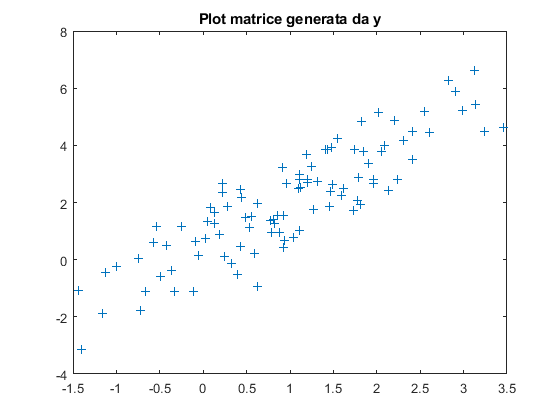

title('Plot matrice generata da y')

3. Modifcare i valori all'interno della matrice di varianza e covarianza definita, generare nuovamente e dati e rappresentarli graficamente.

mu=[1 2]; % cambio i valori di sigma
sigma2=[3 0.5; 0.5 3];
Z = mvnrnd(mu,sigma2,99)

Z =    -1.1509    3.5924
    2.9646    1.6050
   -0.5561    2.2136
    1.4789    2.0104
    0.3398    0.3470
    0.8377    0.8239
    2.2986    1.8273
   -1.8250    3.1975
   -0.6589   -0.5188
    0.8482    1.1185



plot2=plot(Z(:,1),Z(:,2),'+')

plot2 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '+'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×99 double]
              YData: [1×99 double]
              ZData: [1×0 double]

  Show all properties


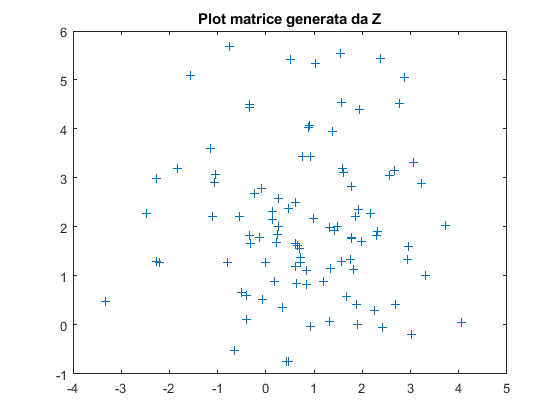

title('Plot matrice generata da Z')

% ottengo un grafico differente

4. Commentare i risultati ottenuti.

La differenza nei risultati ottenuti è dovuto al cambiamento di sigma, infatti sono due campioni diversi ottenuti da  normali bivariate con parametri differenti

Nel plot dei dati generati dalla matrice Z si nota che i punti non sembrano seguire una direzione ben precisa, infatti tendono ad ammassarsi sopratutto nella zona centrale, anche se si nota la presenza di qualche dato anomalo. Si può affermare che, data la mancanza di una relazione tra i punti, i dati sono di fatto incorrelati.

Invece nel plot del campione generato da y la situazione cambia: sembra esserci una marcata relazione lineare tra i dati, infatti a valori alti corrispondono valori alti, e viceversa; non si nota la presenza di particolari dati anonimi.

Si può quindi affermare che i dati godono di un alto livello di correlazione positiva.



% elenco delle funzioni usate

%1

function[Xm,Sx,Rx]=Funzione1(A)
nrow=size(A,1);
u1=ones(nrow,1);
Xm=(pinv(u1)*A)';
Jc=eye(nrow)-(1/nrow)*ones(nrow);
Sx=1/nrow*A'*Jc*A;
D=diag(diag(Sx));
D=D.^0.5;
Rx=D^-1*Sx*D^-1;
end

%2

function[Stampa1,Stampa2,Stampa3] = ChiquadroFinale(BF,BS,Tipo)
% con Tipo sto chiedendo di scegliere uno dei 3 metodi
% inoltre sto chiedendo di dare due matrici alla funzione 
NumclasseS=size(BS,2);
NumclasseF = size(BF,2);
N = size(BF,1);
CF= BF'*BF*ones(NumclasseF,1);
CS= BS'*BS*ones(NumclasseS,1);
Cfs = BF'*BS;
tCfs=N^-1*Cfs;
rCf=CF/N;
rCs=CS/N;
TabCont = [Cfs,CF;CS',N];
TabNCol=(pinv(BS)*BF)';
col=size(TabNCol,2);
r = size(TabCont,1);
% raccolgo tutti i dati e costruisco altre matrici che serviranno per i vari metodi
if Tipo == 1
Stampa2 = N*(trace(BS'*pinv(BF')*BF'*pinv(BS'))-1)
end
if Tipo == 2
Stampa1 = N^3*trace((BF'*BF)^-1*(tCfs-rCf*rCs')*(BS'*BS)^-1*(tCfs-rCf*rCs')')
end
if Tipo == 3
for i = 1:col
    parti(i) = N*(TabCont(r,i)*(TabNCol(:,i)-rCf)'*inv(BF'*BF)*(TabNCol(:,i)-rCf));
end

 Stampa3 = sum(parti)
end 
end


%3

function[Stampa]=Standard(A)
n=size(A,1)
In=eye(n)
jcc = In-(1/n)*ones(n,1)*ones(n,1)'
Sx= cov(A,1)
D=diag(diag(Sx))
Dnew= D.^0.5
Stampa = jcc*A*Dnew^-1
end